format long

n=20;   % the number of terms to use 
x=0.5;  % value of x 

true_value= exp(x)   

true_value =    1.648721270700128


%% way - 01 (loop - substandard)
tic

for i=1:n
    vec1(i)=x^(i-1) / factorial(i-1);
end
vec1

vec1 =    1.000000000000000   0.500000000000000   0.125000000000000   0.020833333333333   0.002604166666667   0.000260416666667   0.000021701388889   0.000001550099206   0.000000096881200   0.000000005382289   0.000000000269114   0.000000000012232   0.000000000000510   0.000000000000020   0.000000000000001   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000


vec1_fin= cumsum(vec1)

vec1_fin =    1.000000000000000   1.500000000000000   1.625000000000000   1.645833333333333   1.648437500000000   1.648697916666667   1.648719618055555   1.648721168154762   1.648721265035962   1.648721270418251   1.648721270687366   1.648721270699598   1.648721270700108   1.648721270700127   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128



toc

Elapsed time is 0.049768 seconds.


%% way - 02 (loop)
tic

vec2= zeros(1,n);    % pre-allocation -> to store the values of n iterations
for i=1:n
    vec2(i)=x^(i-1) / factorial(i-1);
end
vec2_fin= cumsum(vec2);

toc

Elapsed time is 0.005786 seconds.


%% way - 03 (vectorized)
tic

p= 0:19;            % a vector with the powers of x for vectorized operation
vec3= x.^p ./ factorial(p);   % using element-wise operation
vec3_fin= cumsum(vec3);
vec3_fin

vec3_fin =    1.000000000000000   1.500000000000000   1.625000000000000   1.645833333333333   1.648437500000000   1.648697916666667   1.648719618055555   1.648721168154762   1.648721265035962   1.648721270418251   1.648721270687366   1.648721270699598   1.648721270700108   1.648721270700127   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128   1.648721270700128



toc

Elapsed time is 0.039178 seconds.


check_equality= isequal(vec1_fin,vec2_fin,vec3_fin)  % checking whether all three approaches provided the same result

check_equality = logical
   1


%% Calculating the errors

true_error= true_value - vec1_fin(end)

true_error =      4.440892098500626e-16


relative_true_error = (true_error/true_value) *100

relative_true_error =      2.693537214216206e-14



approx_error= diff(vec3_fin);          
relative_approx_error= (approx_error./ vec3_fin(2:end))*100  

relative_approx_error =   33.333333333333329   7.692307692307693   1.265822784810122   0.157977883096371   0.015795293002684   0.001316257091329   0.000094018275271   0.000005876141859   0.000000326452320   0.000000016322620   0.000000000741935   0.000000000030908   0.000000000001185   0.000000000000040                   0                   0                   0                   0                   0


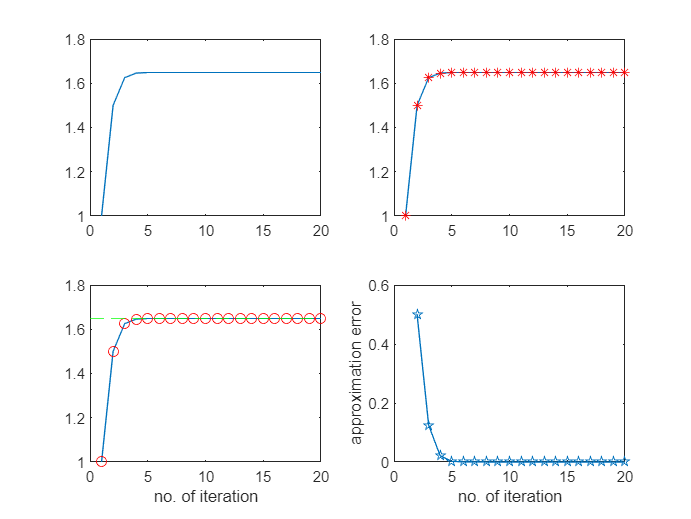

%% plotting
% plotting is a very useful way of representing your findings and results. It's more of an art than coding.
% lets look at differnt ways of plotting and understand the difference

subplot(2,2,1)
plot(1:n,vec3_fin)

subplot(2,2,2)
plot(1:n, vec3_fin,'Marker','*', 'MarkerEdgeColor','r')

subplot(2,2,3)
plot(1:n, vec3_fin, 'Marker','o', 'MarkerEdgeColor','r')
xlabel('no. of iteration')
hold on
yline(true_value,'--g')
hold off

subplot(2,2,4)
plot(2:n, approx_error, 'Marker','p')
xlabel('no. of iteration')
ylabel('approximation error')


% check matlab documentation of the 'plot' function for specifics